# Example script illustrating how to fit a linear pRF model, given

stimulus apertures and voxel response amplitudes (beta weights) per stimulus

%. For background information, see README file or 
%   http://kendrickkay.net/socmodel/

## Add code to the MATLAB path

addpath(genpath(fullfile(pwd,'code')));

## Load data

% load data from the first dataset
load('dataset01.mat','betamn','betase');

## Load stimuli

load('stimuli.mat','conimages', 'images');

## Perform stimulus pre-processing

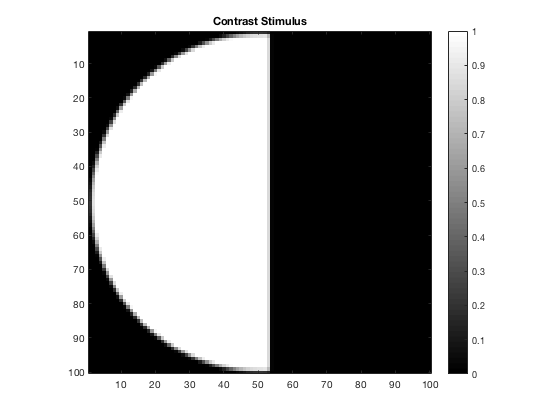

% extract the stimuli we need and then concatenate along the third dimension
stimulus = conimages(1:69);
stimulus = cat(3,stimulus{:});

% resize the stimuli to 100 x 100 (to reduce computational time)
temp = zeros(100,100,size(stimulus,3));
for p=1:size(stimulus,3)
  temp(:,:,p) = imresize(stimulus(:,:,p),[100 100],'cubic');
end
stimulus = temp;

% ensure that all values are between 0 and 1
stimulus(stimulus < 0) = 0;
stimulus(stimulus > 1) = 1;

% inspect one of the stimuli
figure;
imagesc(stimulus(:,:,10));
axis image tight;
colormap(gray);
colorbar;
title('Contrast Stimulus');

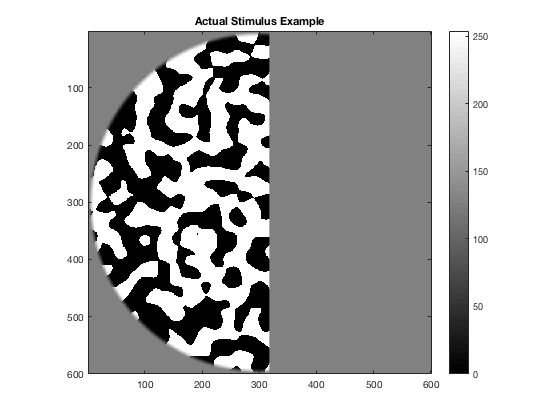


figure
imagesc(images{10}(:,:,1));
axis image tight;
colormap(gray);
colorbar;
title('Actual Stimulus Example');

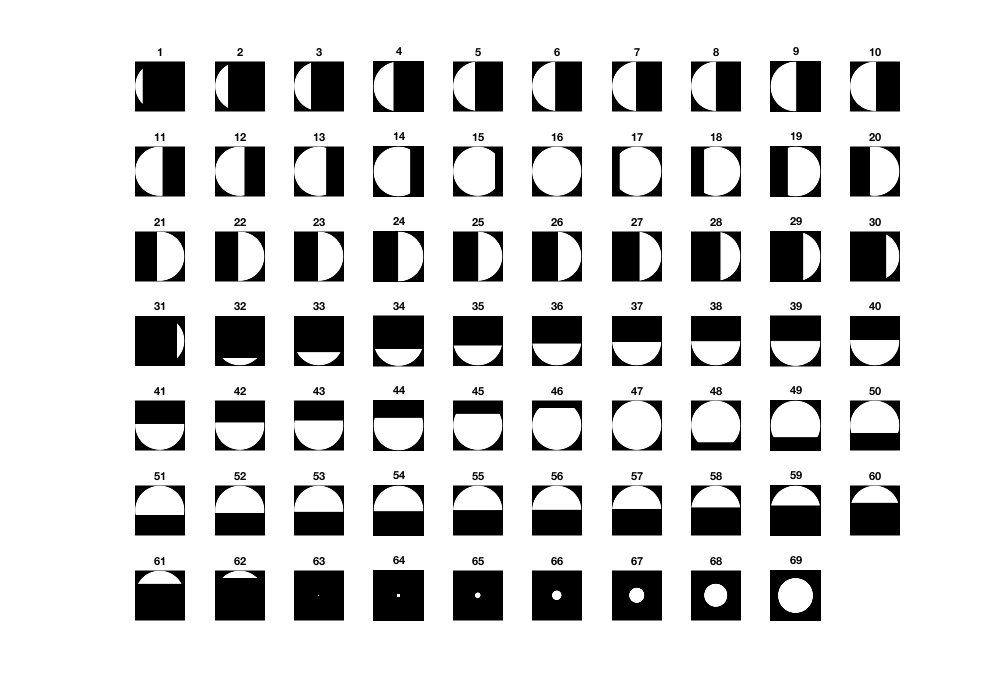

clear images

figure; set(gcf,'Position', [100 100 1000 700])
for ii = 1:69
    subplot(7,10,ii);
    imagesc(stimulus(:,:,ii));
    title(ii);
    axis image tight off;
    colormap(gray);
end

% reshape stimuli into a "flattened" format: 69 stimuli x 100*100 positions
stimulus = reshape(stimulus,100*100,69)';

## Prepare for model fitting

% to perform model fitting, we will be using fitnonlinearmodel.m.  this function
% is essentially a wrapper around MATLAB's lsqcurvefit.m function.  the benefit
% of fitnonlinearmodel.m is that it simplifies input and output issues, deals with
% resampling (cross-validation and bootstrapping), makes it easy to evaluate multiple
% initial seeds, and makes it easy to perform stepwise fitting of models.
%
% to prepare for the call to fitnonlinearmodel.m, we have to define various 
% input parameters.  this is what we will now do.

% define constants
res = 100;  % resolution of the pre-processed stimuli

% the parameters of the Linear model are [R C S G] where
%   R is the row index of the center of the 2D Gaussian
%   C is the column index of the center of the 2D Gaussian
%   S is the standard deviation of the 2D Gaussian
%   G is a gain parameter

% define the initial seed for the model parameters
seed = [(1+res)/2 (1+res)/2 res 1];

% define bounds for the model parameters
bounds = [1-res+1 1-res+1 0   -Inf;
          2*res-1 2*res-1 Inf  Inf];

% issue a dummy call to makegaussian2d.m to pre-compute xx and yy.
% these variables are re-used to achieve faster computation.
[d,xx,yy] = makegaussian2d(res,2,2,2,2);

% we will now define a function that implements the pRF model.  this function
% accepts a set of parameters (pp, a vector of size 1 x 4) and a set of stimuli 
% (dd, a matrix of size A x 100*100) and outputs the predicted response to those 
% stimuli (as a vector of size A x 1).  for compactness, we implement this 
% function as an anonymous function where the parameters are given by pp
% and the stimuli are given by dd.
modelfun = @(pp,dd) pp(4)*(dd*vflatten(... pp(4) is Gain, dd is the stimulus
    makegaussian2d(res,pp(1),pp(2),pp(3),pp(3),xx,yy,0,0)... % 2D isotropic Gaussian
    /(2*pi*pp(3)^2)));  % Normalize the amplitude

% notice that the overall structure of the model is 
%   RESP = GAIN*(STIM*GAU)
% where STIM*GAU represents the dot product between the stimulus and the 2D Gaussian.
% also, note that the division by (2*pi*pp(3)^2) makes it such that the integral
% of the Gaussian is equal to 1 (this aids the interpretation of model parameters).

% now that we have defined modelfun, we are ready to define the final model
% specification.  
model = {seed bounds modelfun};


% define the resampling scheme to use.  here, we use 0, which
% means to just fit the data (no cross-validation nor bootstrapping).
resampling = 0;

% define the metric that we will use to quantify goodness-of-fit.
% here, we use a version of the coefficient of determination (R^2)
% in which variance in the data is computed relative to 0.
% this is sensible since the data being fitted are beta weights that
% represent evoked BOLD responses relative to the baseline signal level
% (which corresponds to 0).
metric = @(a,b) calccod(a,b,[],[],0);

% specify the index of the voxel to fit
ix = 774; % This is from V1
%   To check, load('dataset01.mat'); disp(roilabels{roi(774)})

% finally, construct the options struct that will be passed to fitnonlinearmodel.m
opt = struct( ...
  'stimulus',    stimulus, ...
  'data',        betamn(ix,:)', ...
  'model',       {model}, ...
  'resampling',  resampling, ...
  'metric',      metric);

% do a quick inspection of opt
opt

opt = struct with fields:
      stimulus: [69×10000 double]
          data: [69×1 double]
         model: {[50.5000 50.5000 100 1]  [2×4 double]  @(pp,dd)pp(4)*(dd*vflatten(makegaussian2d(res,pp(1),pp(2),pp(3),pp(3),xx,yy,0,0)/(2*pi*pp(3)^2)))}
    resampling: 0
        metric: @(a,b)calccod(a,b,[],[],0)


## Fit the model

results = fitnonlinearmodel(opt);

*** fitnonlinearmodel: started at 26-Apr-2018 18:28:04. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 1.
      the seed is [50.500 50.500 100.000 1.000 ].

                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         109.944                          2.04
     1         10         82.5221             10           23.1      
     2         15         82.5221             20           23.1      
     3         20         47.4414              5           26.3      
     4         25         47.4414             10           26.3      
     5         30         34.0825            2.5             21      
     6         35         24.9808              5           49.1      
     7         40          21.524             10            124      
     8         45         16.7114        8.940

## Inspect the results

% these are the final parameter estimates
results.params

ans =    61.4024   70.0496    4.1196    6.5934


% this is the R^2 between the model fit and the data
results.trainperformance

ans = 93.2869

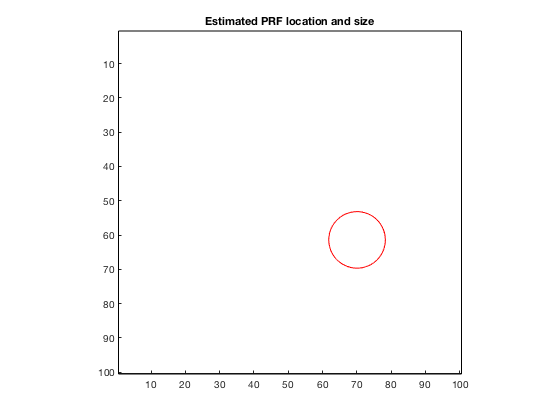

% visualize the parameter estimates
figure; hold on;
pp = results.params;
  % draw a circle indicating the PRF location +/- 2 PRF sizes.
  
drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3));
drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Estimated PRF location and size');

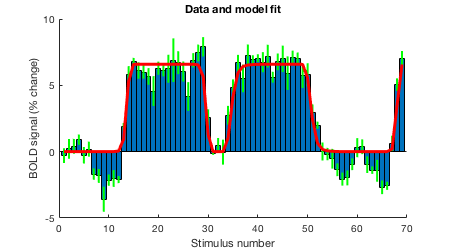

% visualize the data and the model fit
figure; setfigurepos([100 100 450 250]); hold on;
bar(betamn(ix,:),1);
errorbar2(1:69,betamn(ix,:),betase(ix,:),'v','g-','LineWidth',2);
modelfit = modelfun(results.params,stimulus);
plot(1:69,modelfit,'r-','LineWidth',3);
ax = axis;
axis([0 70 ax(3:4)]);
xlabel('Stimulus number');
ylabel('BOLD signal (% change)');
title('Data and model fit');

## Check the predictions for alternate models

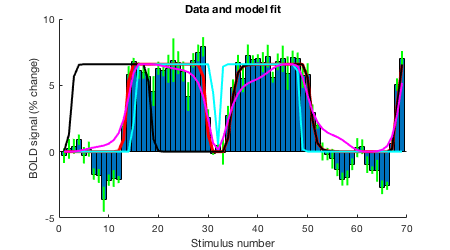

% Suppose we shifted the pRF center by reflecting it over the y-axis
altparams = results.params;
altparams(2) = res+1 - altparams(2);
modelfit2 = modelfun(altparams,stimulus);
gainadjustmnet = max(modelfit) / max(modelfit2);
plot(1:69,modelfit2*gainadjustmnet,'k-','LineWidth',2);

% Suppose we scaled the eccentricity
altparams = results.params;
altparams(1) = 3*(altparams(1) - (res+1)/2) + (res+1)/2;
altparams(2) = 2*(altparams(2) - (res+1)/2) + (res+1)/2;

modelfit2 = modelfun(altparams,stimulus);
gainadjustmnet = max(modelfit) / max(modelfit2);
plot(1:69,modelfit2*gainadjustmnet,'c-','LineWidth',2);

% Suppose we scaled the pRF size
altparams = results.params;
altparams(3) = altparams(3)*3;

modelfit2 = modelfun(altparams,stimulus);
gainadjustmnet = max(modelfit) / max(modelfit2);
plot(1:69,modelfit2*gainadjustmnet,'m-','LineWidth',2);

## Try a different resampling scheme: cross-validation

% define an options struct that specifies leave-one-out cross-validation
optXVAL = opt;
optXVAL.resampling = -2*(eye(69) - 0.5);
optXVAL.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsXVAL = fitnonlinearmodel(optXVAL);

*** fitnonlinearmodel: started at 26-Apr-2018 18:28:11. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 69.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.402 70.050 4.120 6.593 ].
    trainperformance is 93.29. testperformance is 0.00.
  starting resampling case 2 of 69.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.403 70.042 4.129 6.594 ].
    trainperformance is 93.29. testperformance is 0.00.
  starting resampling case 3 of 69.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.402 70.048 4.121 6.593 ].
    trainperformance is 93.30. testperformance is 0.00.
  starting resampling case 4 of 69.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.402 70.049 4.121 6.593 ].
    trainperformance is 93.34. testperformance 

% this is the R^2 between the model predictions and the data.
% notice that this cross-validated R^2 is lower than the
% R^2 of the full fit obtained previously.
resultsXVAL.aggregatedtestperformance

ans = 92.3947

## Try a different resampling scheme: bootstrapping

% define an options struct that specifies 50 bootstraps (i.e. draw 
% with replacement from the 69 data points)
optBOOT = opt;
optBOOT.resampling = {50 0};  % the 0 sets the random-number seed to 0
optBOOT.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsBOOT = fitnonlinearmodel(optBOOT);

*** fitnonlinearmodel: started at 26-Apr-2018 18:28:48. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.866 70.477 3.664 6.740 ].
    trainperformance is 93.51. testperformance is NaN.
  starting resampling case 2 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [60.362 71.190 3.206 6.536 ].
    trainperformance is 96.51. testperformance is NaN.
  starting resampling case 3 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.558 69.283 3.774 6.394 ].
    trainperformance is 93.72. testperformance is NaN.
  starting resampling case 4 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [60.256 71.099 2.767 6.615 ].
    trainperformance is 93.34. testperformance is 

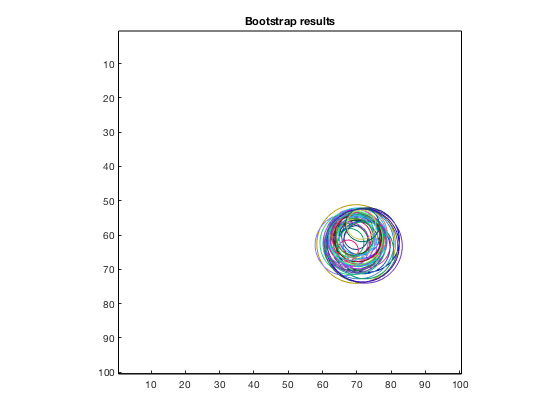

% visualize the parameter estimates
figure; hold on;
for p=1:size(resultsBOOT.params,1)
  pp = resultsBOOT.params(p,:);
  h = drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3));
  set(h,'Color',rand(1,3));
end
drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Bootstrap results');

## Convert solutions to visual field coordinates

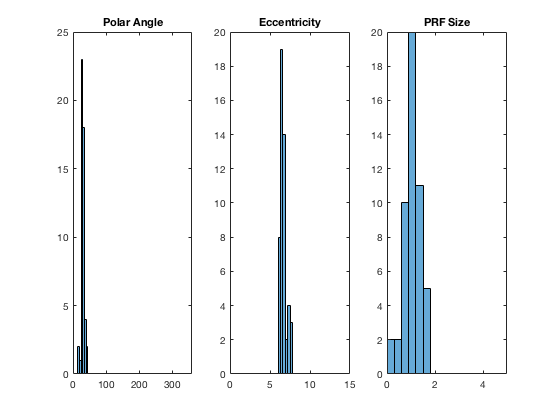

[polarangle, ecc] = cart2pol(resultsBOOT.params(:,2) - seed(1), resultsBOOT.params(:,1) - seed(1));
ecc = ecc / 50.5 * 15;
sigma = resultsBOOT.params(:,3) / 50.5 * 15; 

figure, subplot(1,3,1)
histogram(rad2deg(polarangle))
title('Polar Angle')
xlim([0 360])

subplot(1,3,2)
histogram(ecc)
title('Eccentricity')
xlim([0 15])

subplot(1,3,3)
histogram(sigma)
title('PRF Size')
xlim([0 5])

## Example of how to simulate model responses

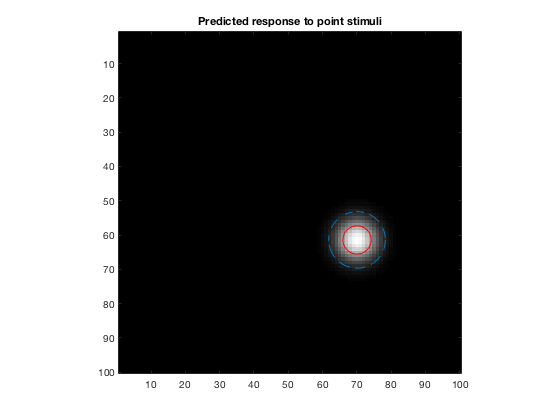

% let's take the model fitted to the full dataset and compute
% the predicted response of the model to some new stimuli.

% let's compute the response of the model to a point stimulus
% that is positioned at different locations in the visual field.
resp = zeros(res,res);
for r=1:res
  for c=1:res
    stim0 = zeros(res,res);
    stim0(r,c) = 1;
    resp(r,c) = modelfun(results.params,flatten(stim0));
  end
end

% visualize the results
figure; 
mx = max(resp(:));
imagesc(resp,[0 mx]);


axis image tight;
colormap(gray);
title('Predicted response to point stimuli');

hold on
pp = results.params;
h = drawellipse(pp(2),pp(1),0,pp(3),pp(3));
h = drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3), [], [], '--');


% notice that the results return the pRF.